# アンチワインドアップのアルゴリズム

## 背景

[UAVのホバリング Part 2](matlab:open('UHG_control_UAV_p2'))で示したように、アクチュエータの上下限が存在するシステムにおいては、積分器の積分操作を適切に制限しないと、過剰なオーバーシュートが発生することがある（なお、現実世界の全てのアクチュエータには上下限が存在している）。ここでは、そのオーバーシュートを抑制するための「アンチワインドアップ」アルゴリズムについて解説する。

## 種類

アンチワインドアップの基本的な考え方としては、偏差（PID制御器の入力）の符号が変化したらすぐに反転できるように、積分器の積分保持量の大きさを増加させないようにすることである。

Simulinkの標準ライブラリの「PID Controller」ブロックには、アンチワインドアップを適用するオプションが実装されている。選択できるアルゴリズムは「固定(clamping)」と「逆解析(back-calculation)」である。

## 固定

PID制御器の出力が上下限を上回り、積分器出力とPID制御器の入力の符号が同じ場合に積分を停止する。PID制御器の入力が上下限を上回り、積分器出力とPID制御器の入力の符号が反対の場合に積分を再開する。固定は条件付き積分と呼ばれることもある。

'AWU_clamping.slx'にて、固定のアルゴリズムを持つPID制御のシステムを構築した。モデルを開いて確認すること。

mode_name = 'AWU_clamping';
open_system(mode_name);

'clamping'という名前のStateflowチャートが、固定のアルゴリズムを表している。'clamping'内のフローチャートを確認すること。

モデルを実行し、動作を確認する。

sim(mode_name);
AWU_clamping_plot_in_SDI;

結果をFig.1に示す。

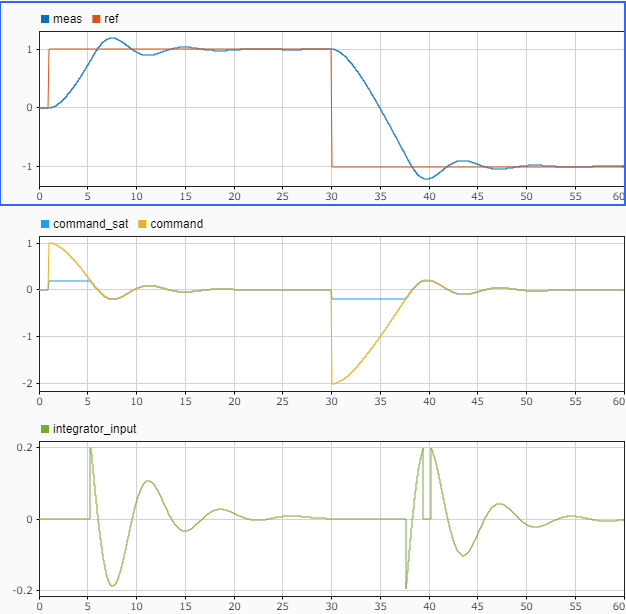

Fig.1 固定アルゴリズムの実行結果

例えば1～5.3秒時にPID制御の出力が上下限値を上回っている。この時、(指令値 - 制御量)はプラスであるため、積分器の入力は0となっている。(指令値 - 制御量)が小さくなり、操作量が上限を下回るようになる5.3秒以降に、通常通り(指令値 - 制御量)が積分器に入力されるようになる。

### Task 1

ここで、モデルを修正し、固定アルゴリズムを無効にしてシミュレーションを実行し、アルゴリズムの有無による応答の違いを確認すること。

## 逆解析

PID制御器の出力が上下限を上回る際、上回った分を積分器に戻すことで、積分器のワインドアップを解消する。

'AWU_back_calculation.slx'にて、固定のアルゴリズムを持つPID制御のシステムを構築した。モデルを開いて確認すること。

mode_name = 'AWU_back_calculation';
open_system(mode_name);

'Kb'は逆解析のゲインである。通常は、`Kb = I_gain` または `Kb = sqrt(I_gain*D_gain)` (微分器を含むコントローラーの場合) を設定すればよい。

モデルを実行し、動作を確認する。

sim(mode_name);
AWU_back_calculation_plot_in_SDI;

結果をFig.2に示す。

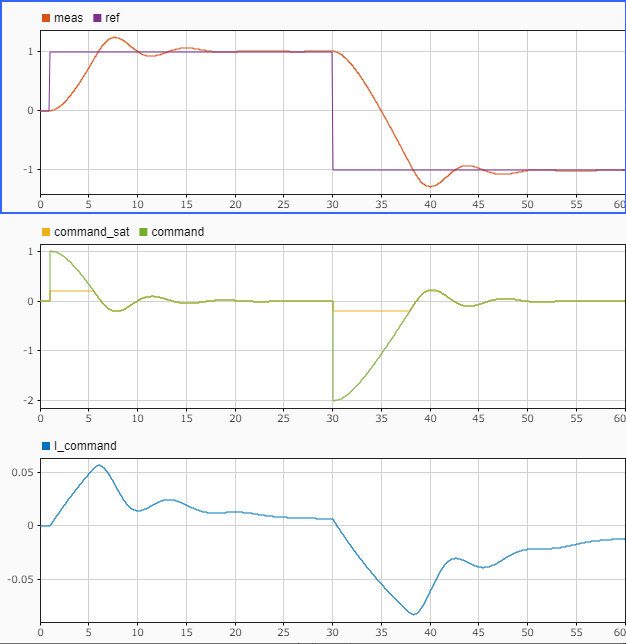

Fig.2 逆解析アルゴリズムの実行結果

例えば、1～5.4秒時に、PID制御の出力が上下限値を上回っている。この時、(操作量 - 操作量の上限)を、積分器の入力に加算するため、積分器の上昇を抑制している。操作量が上限を下回った5.4秒以降、積分器の変動が本来の速度に戻っている。

### Task 2

ここでモデルを修正し、[UAVのホバリング Part 2](matlab:open('UHG_control_UAV_p2'))の例で示したように、マルチコプターの機体がしばらくの間抑えられている、というような条件においても、アンチワインドアップ制御が有効であることを確認すること。また、逆解析アルゴリズムでは、機体が抑えられている間、積分保持量は最終的に一定の値に収束することを確認すること。

逆解析は、固定と比較すると、むだ時間が比較的大きいプラントに効果的な場合があるとされている [1]。

## 参考文献

[1] Visioli, A., "Modified Anti-Windup Scheme for PID Controllers," IEE Proceedings - Control Theory and Applications, Vol. 150, Number 1, January 2003

*Copyright 2021 The MathWorks, Inc.*